# LSTM Model Generator

This script is intended to service as an example of how to load processed feature data and construct a statistical model from it. The confusion matrix will be saved to a csv file. In particular, long short term memory RNN model is built here.

## Create features

The format of the required featuers for LSTM models is significantly different than that required by traditional learners such as logistic regression, SVM, and decision trees. THe feature generation scripts need to be updated to support the formate required here. So far, the following scripts have been updated:

- CepstralFreatureGenerator.mlx

## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamples' directory. 

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesSNR6Cepstral26featuresT2sCell";

% Model storage directory and file name
modeldir = fullfile(basedir,'data','Models');
modelfilename = "ModelSNR6Cepstral26featuresLSTM";

% modelresultscsv = "ModelResults.csv";

% Create pool of MATLAB workers
% tic; parpool('local',4); toc


## Model parameters

List and define model parameters.

% model type
type = "LSTM_RNN";

% # cross-validation folds
KFolds = 5;

## Load features

Load the features table from the processed data. 

% Load feature table
features = load(fullfile(featuredir,featurefilename));
xfeatures = features.xfeaturescell;
xresponses = categorical(features.xresponsescell);
xresponseslong = features.xfeatures.contaminated;

numFeatures = size(xfeatures{1},1);
numClasses = length(unique(xresponses));

xresponseslongcell = cell(size(xresponses));
for iresponse = 1:length(xresponses)
    xresponseslongcell{iresponse} = repmat(xresponses(iresponse),1,size(xfeatures{iresponse},2));
end
xresponses = xresponseslongcell;

## Define model

Define the model and any optional parameters. Use the fitglm function to train a logistic regression model without regularization or use the lassoglm function to fit a logistic regression model with regularization. 

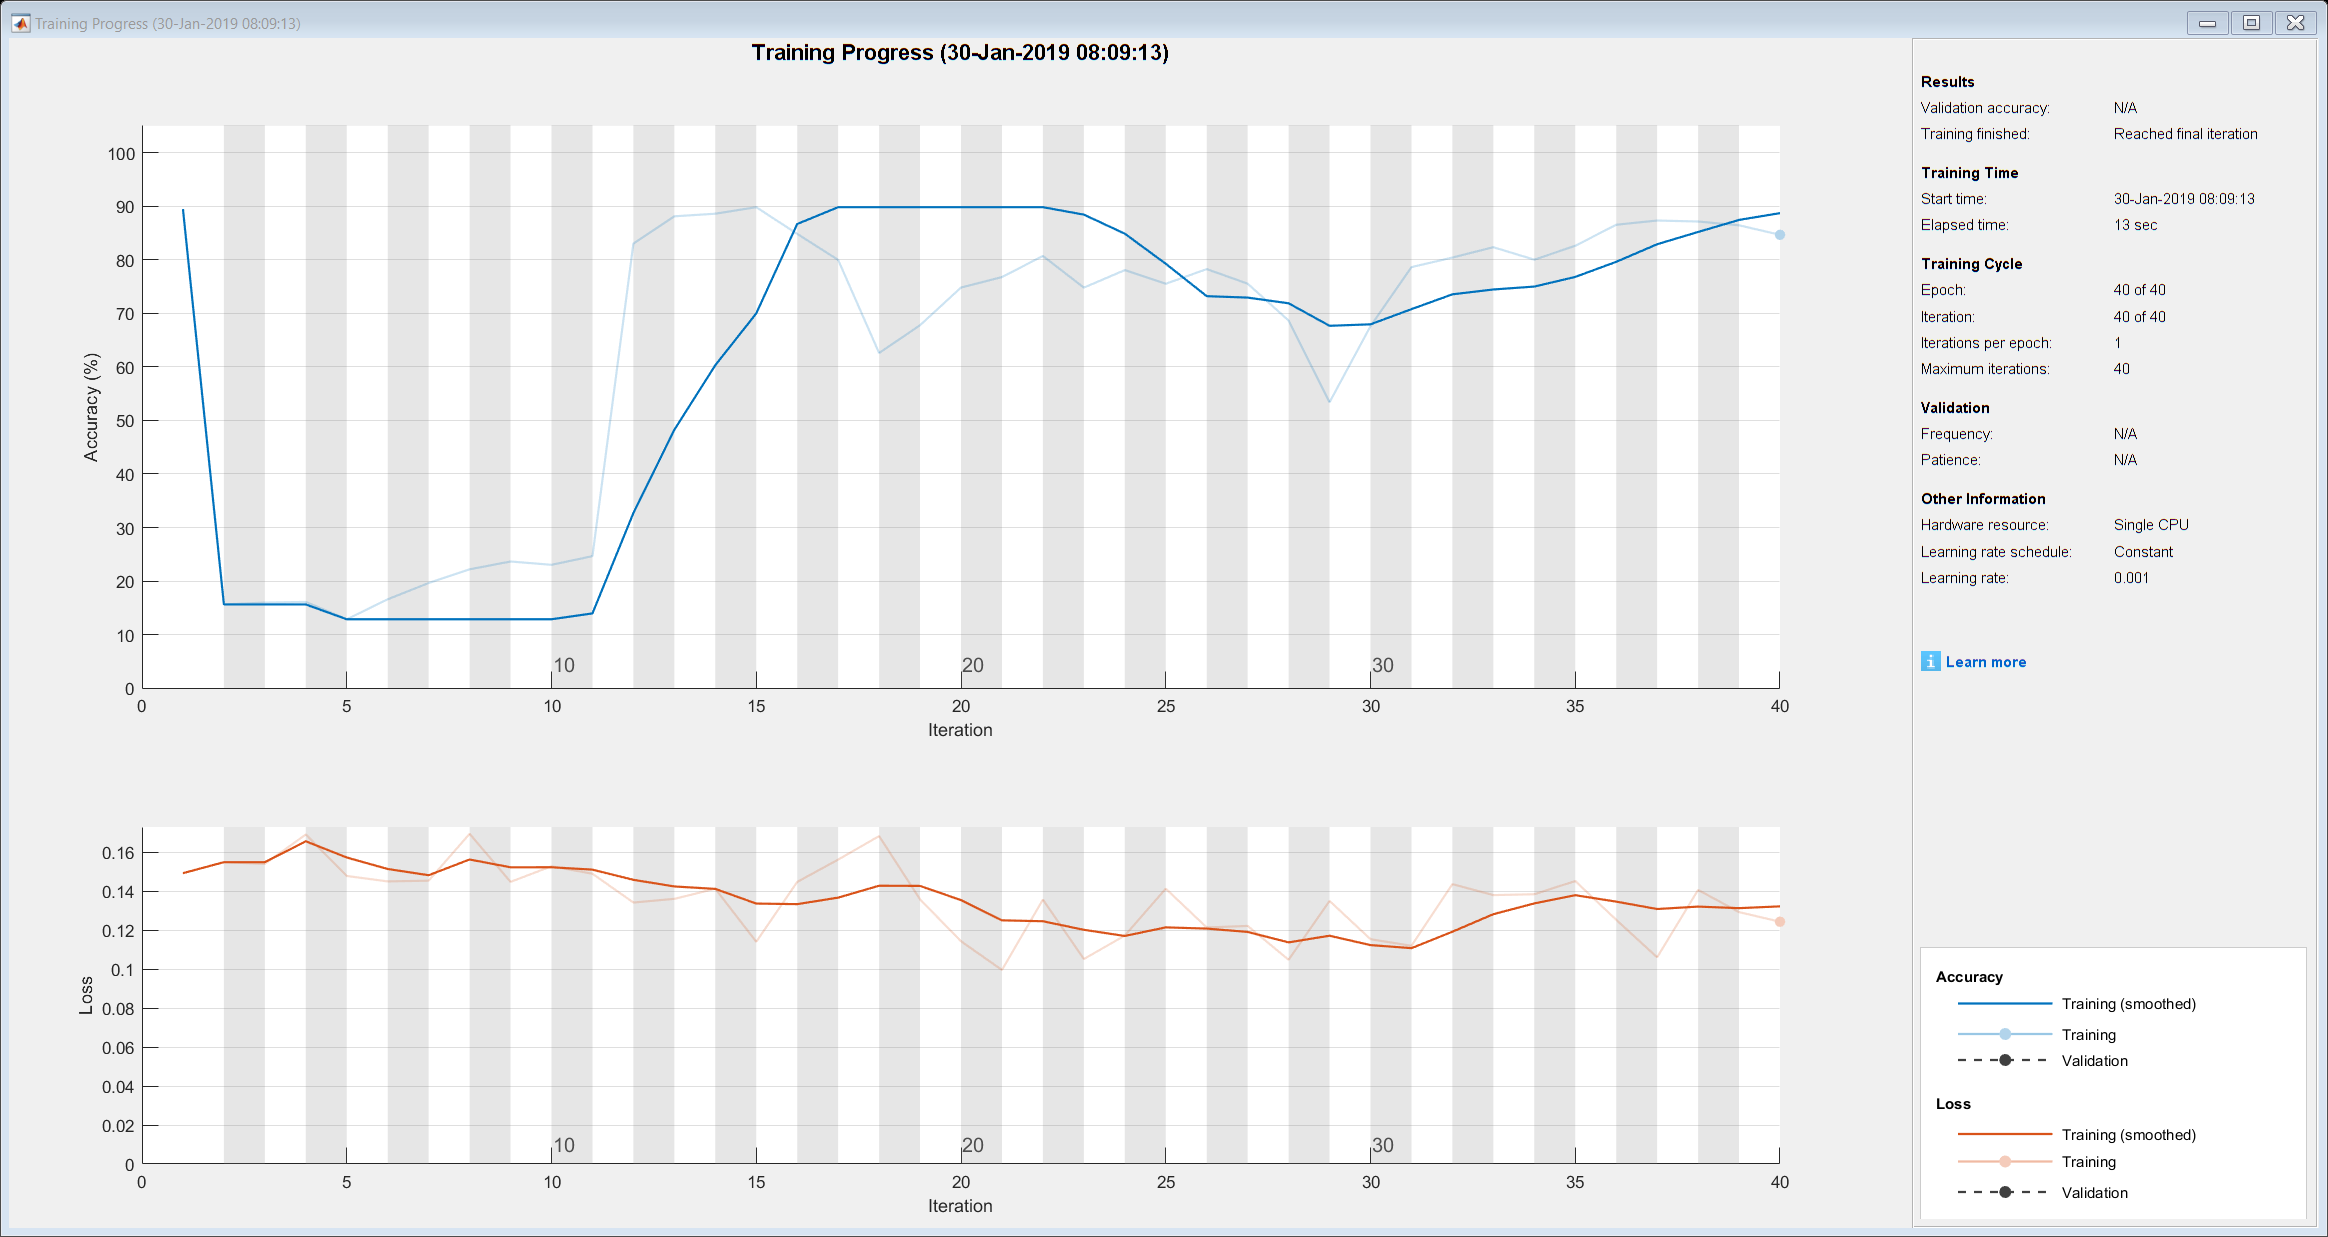

|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       89.47% |       0.1492 |          0.0010 |
|      40 |          40 |       00:00:13 |       84.66% |       0.1243 |          0.0010 |
|========================================================================================|


% Define LSTM network
numHiddenUnits = 100;
layers = [sequenceInputLayer(numFeatures)
          lstmLayer(numHiddenUnits,'OutputMode','sequence')
          fullyConnectedLayer(numClasses)
          softmaxLayer
          classificationLayer];

% Set training options
maxEpochs = 40;
miniBatchSize = 80;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',1, ...
    'Plots','training-progress');

% Train
tic
rng(42);
[mdlfull,trainInfo] = trainNetwork(xfeatures,xresponses,layers,options);

toc

Elapsed time is 14.476760 seconds.


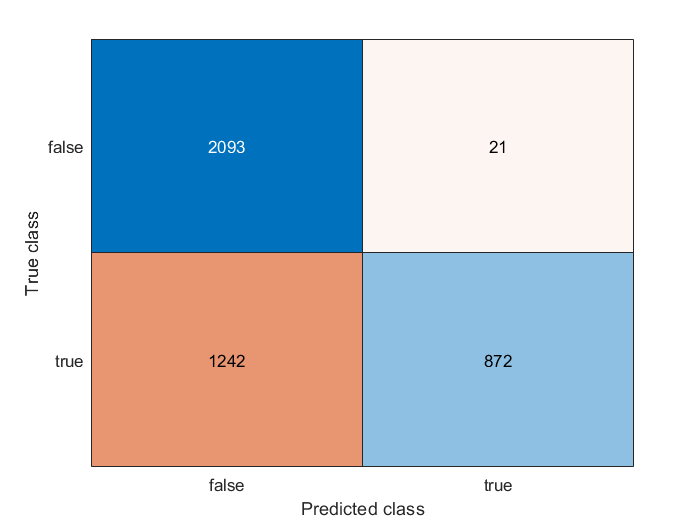

% Make prediction
foldPred = classify(mdlfull,xfeatures);
% foldPred = predict(mdlfull,xfeatures);

% Reshape responses for comparison
xresponsesPred = [foldPred{:}]';

% Score
[accuracyFrac,fpr,fnr,f1] = scoreModel(logical(xresponseslong),xresponsesPred == "true"); %#ok
confusionchart(logical(xresponseslong),xresponsesPred == "true");


disp("Accuracy is (%): " + num2str(accuracyFrac))

Accuracy is (%): 0.70128


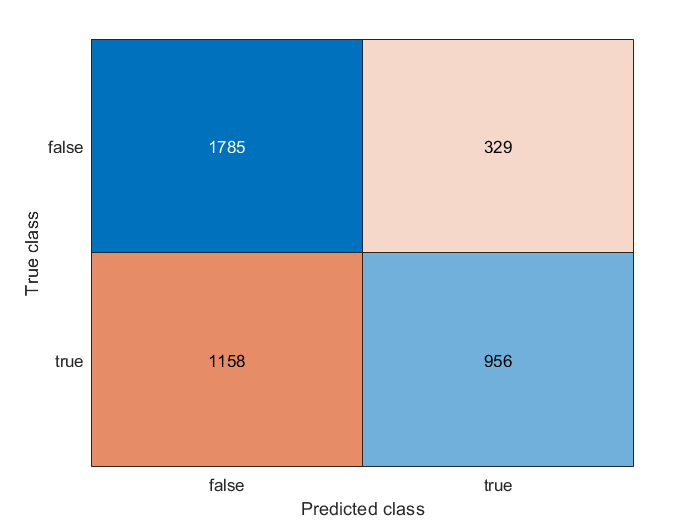

% Perform cross-validation
cvp = cvpartition(features.xresponsescell,'KFold',KFolds); % Stratified by default

% Initialize the predictions to the proper sizes
validationPredictions = xresponses;
numObservations = cvp.NumObservations;
numClasses = 2;
validationScores = table('Size',[KFolds 2],'VariableTypes',{'double' 'double'},'VariableNames',{'Accuracy' 'F1Score'});
for ifold = 1:KFolds
    % Split data
    xfeaturestest = xfeatures(cvp.test(ifold));
    xresponsestest = xresponses(cvp.test(ifold));
    xfeaturestrain = xfeatures(cvp.training(ifold));
    xresponsestrain = xresponses(cvp.training(ifold));
    
    % 'ValidationData',{X,Y},'ValidationFrequency',10
    options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',0, ...
    'Plots','none', ...
    'ValidationData',{xfeaturestest,xresponsestest}, ...
    'ValidationFrequency',5);

    % Train
    rng(42);
    mdlfold = trainNetwork(xfeaturestrain,xresponsestrain,layers,options);
    
    % Make prediction
    foldPred = classify(mdlfold,xfeaturestest);
    
    % Reshape responses for comparison
    xresponsestest = [xresponsestest{:}]';
    xresponsesPred = [foldPred{:}]';
    
    % Score
    [accuracyFrac,fpr,fnr,f1] = scoreModel(xresponsestest,xresponsesPred); %#ok
    
    % Store predictions in the original order
    validationScores.Accuracy(ifold) = accuracyFrac;
    validationScores.F1Score(ifold) = f1;
    validationPredictions(cvp.test(ifold)) = foldPred;
end

% Score
validationPredictions = [validationPredictions{:}]';
[accuracyFrac,fpr,fnr,f1] = scoreModel(logical(xresponseslong),validationPredictions == "true");
confusionchart(logical(xresponseslong),validationPredictions == "true");

disp("Median Accuracy is (%): " + num2str(median(validationScores.Accuracy)))

Median Accuracy is (%): 0.61776


## Save output

Save the fitted model and write results to csv file. 

% Save to file
% save(fullfile(modeldir,modelfilename))

% Write results to csv file
% fid = fopen(fullfile(modeldir,modelresultscsv),'a');
% fspec = '%s,%s,%s,%s,%17.15f,%i,%i,%i,%i \n';
% fprintf(fid,fspec,type,modelfilename,features.type,features.featurefilename,accuracyFrac,confMat(1,1),confMat(2,1),confMat(1,2),confMat(2,2));
% fclose(fid);